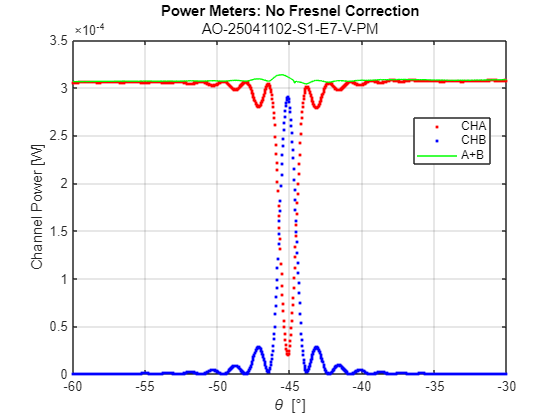

% New hologram fitting dashboard for Power Meter HMT data.
 
clear; close('all'); clc;

% HMT Data file directory
data_directory = "C:\Users\Fresnel\OneDrive - UCB-O365\Holography\Holography Directory\AS_2025_04_11_02_GH_ReShoots\E7\AO-25041102-S1-E7-V-PM.mat";
DATA = loadPMfromHMT(data_directory);

% Plot the raw channel data from the angle scan:
plotRawChannelData(DATA);

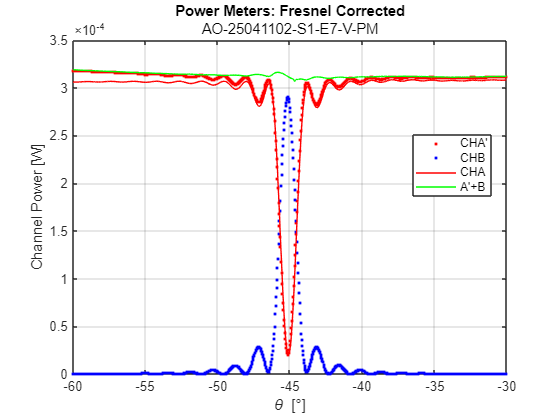


% Plot the Channel A corrected signal (used for DE calculation):
plotFresnelCorrectedChannelData(DATA);

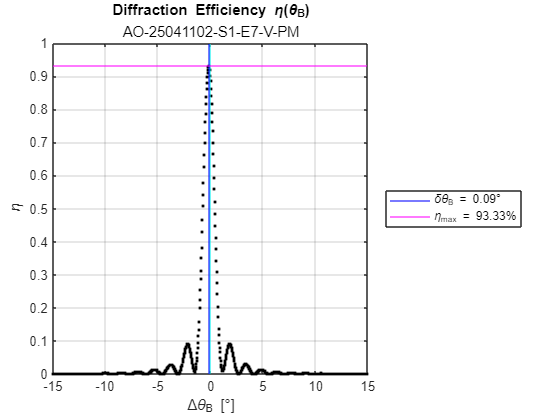


% Plot the diffraction efficiency curve about the Bragg angle:
plotDiffractionEfficiency(DATA);

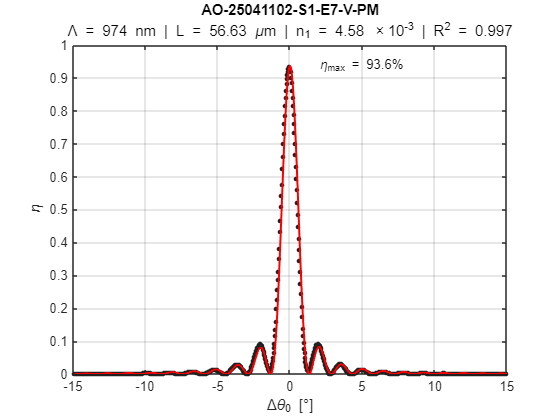


% Plot the existing CWT fit from the HMT
plotCWTfromHMT(DATA);

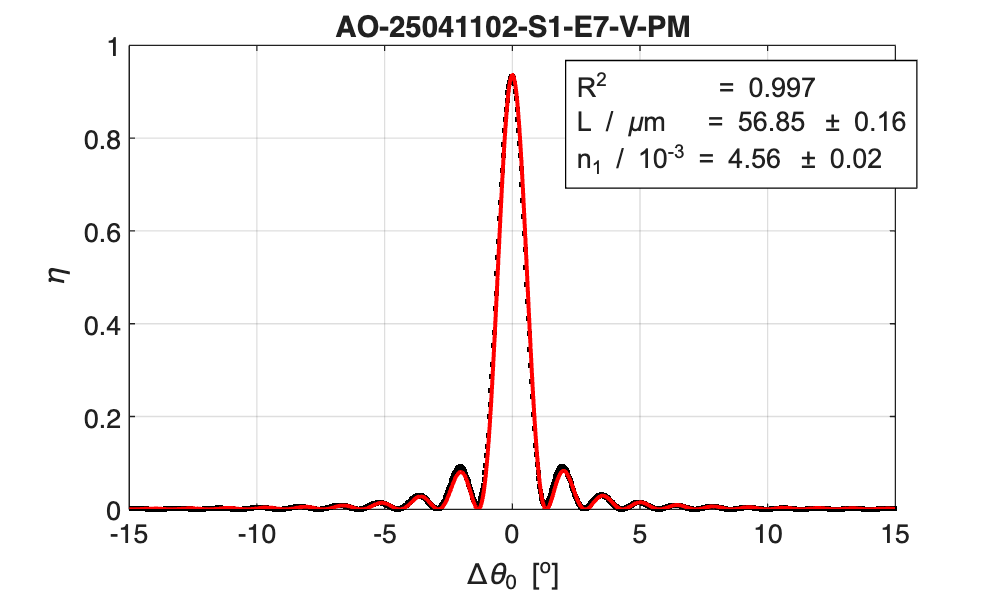

% NEW angle scan fit to Kogelnik/Uchida coupled-wave theory for TP-VHGs:
% New fit input variables
CWT_Fit.Write_Angle = 7.97; % Symmetric angle inside material
CWT_Fit.Nominal_n0  = 1.5; % Base refractive index
CWT_Fit.Guess_n1    = 0.001; % Startng point for n1 fit
CWT_Fit.Guess_L     = 10; % Starting point for L fit
 

% Fit to CWT
fitHMTtoCWT(DATA, CWT_Fit);

function DATA = loadPMfromHMT(data_directory)
    load(data_directory);
    
    % Logic to deal with old vs new structure
    if exist("HMT_OUT",'var') == 1
        % Isolate old data structure
        OLDDATA = HMT_OUT; clear("HMT_OUT");
        
        % Restructure old data into new format
        DATA = restructureOldHMTData(OLDDATA);
    else
        DATA = HMT_DATA; clear("HMT_DATA");
    end
end

function [start_angle, stop_angle] = defineAngleRanges(bisector_angle, scan_range)
    % Define the stage angle ranges
    start_angle = bisector_angle + (scan_range / 2);
    stop_angle  = bisector_angle - (scan_range / 2);
end

function angle_centered = shiftAngles(angle_vec, bisector_angle)
    % Center the angle stage data about the bisector (detuning)
    angle_centered = angle_vec - bisector_angle;
end

function plotRawChannelData(DATA)
    % Function to plot the raw angle scan channel data.
    % Parse data structure
    angle_vec        = DATA.AS.Angle_Vec_AS;
    channel_A        = DATA.AS.Channel_A_AS;
    channel_B        = DATA.AS.Channel_B_AS;
    measurement_name = DATA.AS.Measurement_Name_AS;
    scan_range       = DATA.AS.Scan_Range_AS;
    bisector_angle   = DATA.AS.Bisector_Angle_AS;
    
    % Calculate angle ranges
    [start_angle, stop_angle] = defineAngleRanges(bisector_angle, scan_range);
    
    % Make figure
    figure;
    plot(angle_vec, channel_A,'r.'); hold("on");
    plot(angle_vec, channel_B,'b.'); grid("on");
    plot(angle_vec, channel_A + channel_B, 'g');
    title('Power Meters: No Fresnel Correction');
    subtitle(measurement_name);
    xlabel('\theta [\circ]'); xlim([stop_angle, start_angle]);
    ylabel('Channel Power [W]');
    legend('CHA','CHB','A+B',Location='best');
end

function plotFresnelCorrectedChannelData(DATA)
    % Function to plot the Fresnel correctee angle scan channel data.
    % Parse data structure
    angle_vec           = DATA.AS.Angle_Vec_AS;
    channel_A_corrected = DATA.AS.Channel_A_Corrected;
    channel_A           = DATA.AS.Channel_A_AS;
    channel_B           = DATA.AS.Channel_B_AS;
    measurement_name    = DATA.AS.Measurement_Name_AS;
    scan_range          = DATA.AS.Scan_Range_AS;
    bisector_angle      = DATA.AS.Bisector_Angle_AS;
    
    % Calculate angle ranges
    [start_angle, stop_angle] = defineAngleRanges(bisector_angle, scan_range);
    
    % Make figure
    figure;
    plot(angle_vec, channel_A_corrected,'r.'); hold("on");
    plot(angle_vec, channel_B,'b.'); grid("on");
    plot(angle_vec, channel_A,'r');
    plot(angle_vec, channel_A_corrected + channel_B, 'g');
    title('Power Meters: Fresnel Corrected');
    subtitle(measurement_name);
    xlabel('\theta [\circ]'); xlim([stop_angle, start_angle]);
    ylabel('Channel Power [W]');
    legend("CHA'",'CHB','CHA',"A'+B",Location='best');
end

function plotDiffractionEfficiency(DATA)
    % Function to plot the Fresnel correctee angle scan channel data.
    % Parse data structure
    angle_vec           = DATA.AS.Angle_Vec_AS;
    DE                  = DATA.AS.DE_AS;
    measurement_name    = DATA.AS.Measurement_Name_AS;
    scan_range          = DATA.AS.Scan_Range_AS;
    bisector_angle      = DATA.AS.Bisector_Angle_AS;
    angle_Bragg_peak    = DATA.AS.Angle_Bragg_Max;
    DE_max              = DATA.AS.DE_max;
    angle_shift         = DATA.AS.Angle_Shift;
    
    % Center angle data about bisector
    angle_centered = shiftAngles(angle_vec, bisector_angle);
    
    % Calculate angle ranges
    detune_stop_angle = -(scan_range / 2);
    detune_start_angle = -detune_stop_angle;
    
    % Make strings for reporting data
    angle_shift_str = sprintf('\\delta\\theta_{B} = %.2f\\circ',angle_shift);
    peak_DE_str     = sprintf('\\eta_{max} = %.2f%%',DE_max*100);
    
    % Make figure
    figure;
    plot(angle_centered, DE,'k.'); grid on;
    xline(0,'c'); % Stage center angle
    xline(angle_Bragg_peak - bisector_angle,'b'); % Bragg peak angle
    yline(DE_max,'m'); % Peak efficiency
    title('Diffraction Efficiency \eta(\theta_{B})');
    subtitle(measurement_name);
    xlabel('\Delta\theta_{B} [\circ]'); xlim([detune_stop_angle, detune_start_angle]);
    ylabel('\eta');           ylim([0 1]);
    legend('','',angle_shift_str,peak_DE_str,'location','eastoutside');
    clear('angle_shift_str'); clear('peak_DE_str');
end

function plotCWTfromHMT(DATA)
    % Function to plot the existing CWT fit from the HMT file.
    % Parse data structure
    angle_vec           = DATA.AS.Angle_Vec_AS;
    DE                  = DATA.AS.DE_AS;
    measurement_name    = DATA.AS.Measurement_Name_AS;
    scan_range          = DATA.AS.Scan_Range_AS;
    bisector_angle      = DATA.AS.Bisector_Angle_AS;
    Lambda              = DATA.In_Data.Lambda;
    angle_shift         = DATA.AS.Angle_Shift;
    
    fit_result = DATA.CWT.out.fitresult;
    fit_L      = DATA.CWT.out.L;
    fit_n1     = DATA.CWT.out.n1;
    fit_GoF    = DATA.CWT.out.gof.rsquare;
    
    % Center angle data about bisector - needed for fitting
    angle_centered = shiftAngles(angle_vec, bisector_angle);
    angle_centered = angle_centered + angle_shift;
    
    % Calculate angle ranges
    detune_stop_angle  = -(scan_range / 2);
    detune_start_angle = -detune_stop_angle;
    
    % Make strings for reporting data
    fit_max = fit_result(0);
    peak_DE_str     = sprintf('\\eta_{max} = %.1f%%',fit_max*100);
    fit_result_str  = sprintf('\\Lambda = %i nm | L = %.2f \\mum | n_1 = %.2f \\times10^{-3} | R^2 = %.3f',Lambda,fit_L*(10^6), fit_n1*(10^3), fit_GoF);
    
    % Make figure
    figure;
    plot(fit_result,'r', angle_centered, DE); legend("off"); grid("on");
    text(2, fit_max, peak_DE_str)
    title(measurement_name);
    subtitle(fit_result_str);
    xlabel('\Delta\theta_{0} [\circ]'); xlim([detune_stop_angle, detune_start_angle]);
    ylabel('\eta');           ylim([0 1]);
    
    clear('angle_shift_str'); clear('peak_DE_str');
end

function fitHMTtoCWT(DATA, CWT_Fit_IN)
    % Function to fit the HMT angle scan data to CWT
    % Parse data structure
    angle_vec           = DATA.AS.Angle_Vec_AS;
    DE                  = DATA.AS.DE_AS;
    measurement_name    = DATA.AS.Measurement_Name_AS;
    scan_range          = DATA.AS.Scan_Range_AS;
    bisector_angle      = DATA.AS.Bisector_Angle_AS;
    write_wavelength    = DATA.AS.Write_Wavelength;
    read_wavelength     = DATA.AS.Read_Wavelength_AS;
    angle_shift         = DATA.AS.Angle_Shift;
    
    % Center angle data about bisector - needed for fitting
    angle_centered = shiftAngles(angle_vec, bisector_angle);
    % Apply additional angle shift - needed for fitting
    angle_centered = angle_centered + angle_shift;
    
    % Calculate angle ranges
    detune_stop_angle = -(scan_range / 2);
    detune_start_angle = -detune_stop_angle;
    
    % Parse fitting parameters
    write_angle = CWT_Fit_IN.Write_Angle;
    nominal_n0  = CWT_Fit_IN.Nominal_n0;
    guess_L     = CWT_Fit_IN.Guess_L;
    guess_n1    = CWT_Fit_IN.Guess_n1;
    
    % Fit and make figure
    figure;
    FitBraggSelectivity(angle_centered,DE, ...
        'PlotKSpace',  false, ...
        'PlotPhi',     false, ...
        'PlotA',       false, ...
        'lambdaWrt0',  write_wavelength*(10^-09), ...
        'lambdaRed0',  read_wavelength*(10^-09), ...
        'RefWrtTheta', -write_angle,   'ObjWrtTheta', write_angle, ...
        'nWrt',        nominal_n0,     'nRed',        nominal_n0, ...
        'L0',          guess_L*(10^-6),'n10',         guess_n1, ...
        'PlotTitle',   measurement_name);
    xlim([detune_stop_angle, detune_start_angle]);
    grid on;
end

function DATA = restructureOldHMTData(OLDDATA)
    % Function to restructure the old HMT data into the new format
    DATA.AS.Angle_Vec_AS = OLDDATA.AS.AngleVec;
    DATA.AS.Channel_A_AS = OLDDATA.AS.Channel_A;
    DATA.AS.Channel_B_AS = OLDDATA.AS.Channel_B;
    DATA.AS.Channel_A_Corrected = OLDDATA.AS.Channel_A_Corrected;
    DATA.AS.Channel_B_Corrected = OLDDATA.AS.Channel_B_Corrected;
    DATA.AS.Measurement_Name_AS = OLDDATA.AS.MeasurementName;
    DATA.AS.Scan_Range_AS       = OLDDATA.AS.ScanRange;
    DATA.AS.Bisector_Angle_AS   = OLDDATA.AS.BisectorAngle;
    DATA.AS.Write_Wavelength    = OLDDATA.AS.WriteWavelength;
    DATA.AS.Read_Wavelength_AS  = OLDDATA.AS.ReadWavelength;
    DATA.In_Data.Lambda      = OLDDATA.IN_data.Lambda;
    DATA.AS.DE_AS            = OLDDATA.AS.DE;
    DATA.AS.Angle_Bragg_Max  = OLDDATA.AS.BraggPeakAngle;
    DATA.AS.DE_max           = OLDDATA.AS.PeakDE;
    DATA.AS.Angle_Shift      = OLDDATA.AS.AngleShift;
    DATA.CWT.out.fitresult   = OLDDATA.CWT.out.fitresult;
    DATA.CWT.out.L           = OLDDATA.CWT.out.L;
    DATA.CWT.out.n1          = OLDDATA.CWT.out.n1;
    DATA.CWT.out.gof.rsquare = OLDDATA.CWT.out.gof.rsquare;
end